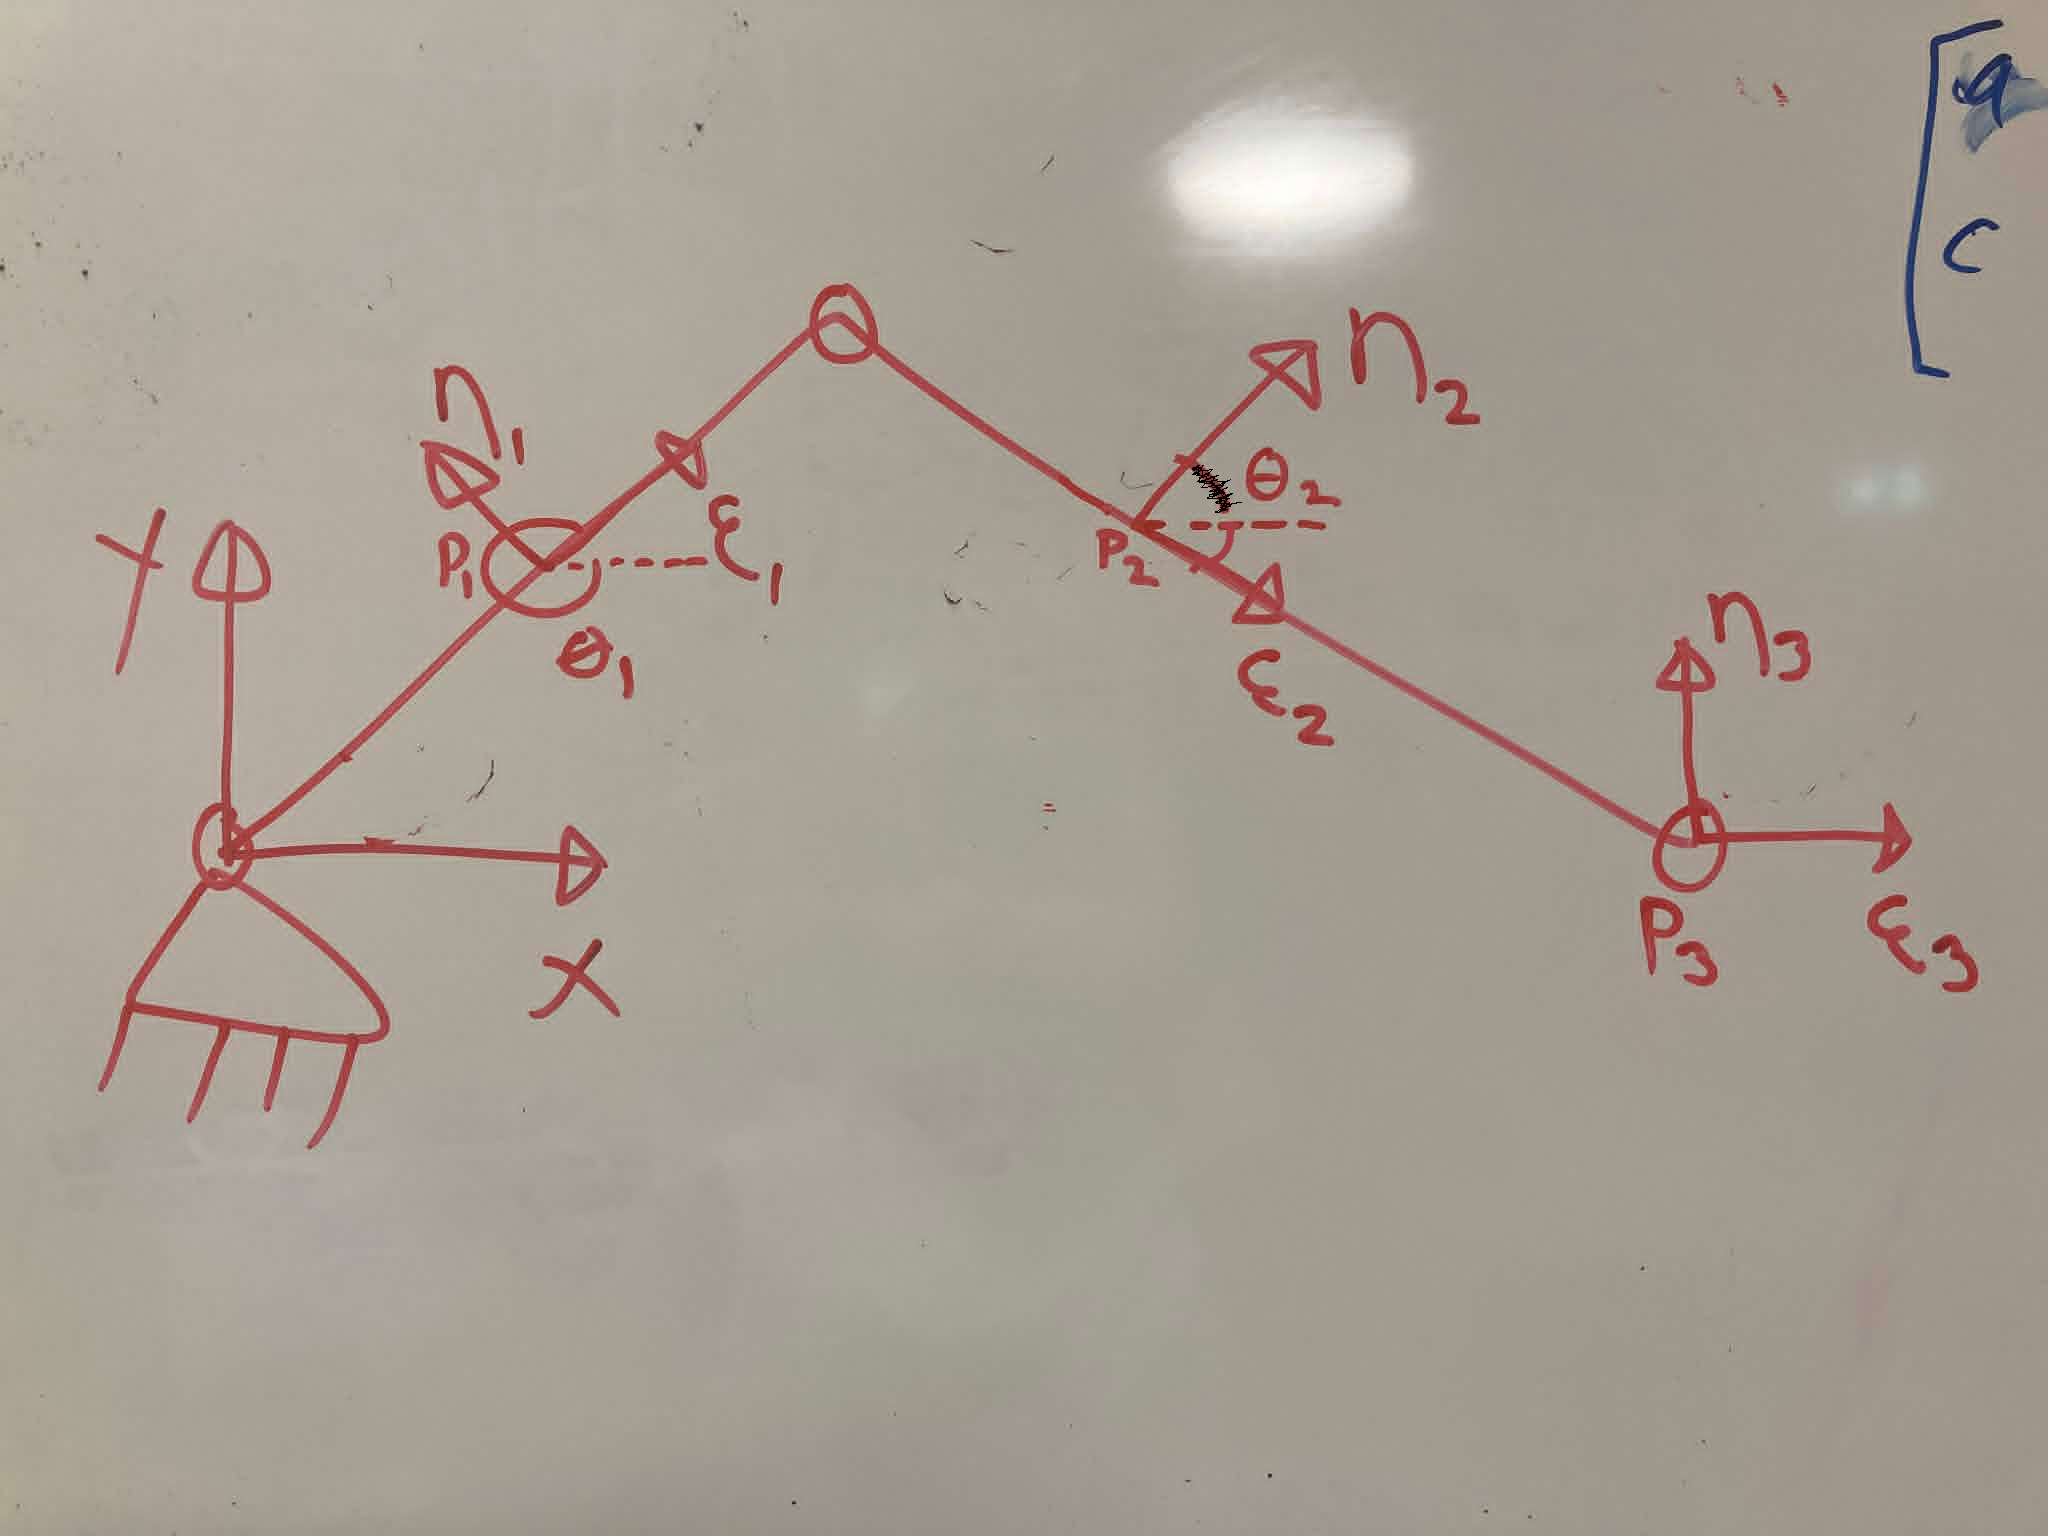

%Symbolic derivation for torque function
syms x1 y1 x2 y2 x3 y3 th1 th2 th3 x real
syms t l_1 l_2 real

% Your A-matrix entries evaluated at the orientations
    A1_11 = cos(th1);
    A1_12 = -sin(th1);
    A1_21 = sin(th1);
    A1_22 = cos(th1);

    A2_11 = cos(th2);
    A2_12 = -sin(th2);
    A2_21 = sin(th2);
    A2_22 = cos(th2);

    A3_11 = cos(th3);
    A3_12 = -sin(th3);
    A3_21 = sin(th3);
    A3_22 = cos(th3);

%P-vectors
    P11_1 = -l_1/2;
    P11_2 = 0;
    P21_1 = l_1/2;
    P21_2 = 0;
    P22_1 = -l_2/2;
    P22_2 = 0;
    P32_1 = l_2/2;
    P32_2 = 0;
    P33_1 = 0;
    P33_2 = 0;

phi = [
        x1 + A1_11*P11_1 + A1_12*P11_2;
        y1 + A1_21*P11_1 + A1_22*P11_2;
        x2 - (x1 + (A1_11*P21_1 + A1_12*P21_2) - (A2_11*P22_1 + A2_12*P22_2));
        y2 - (y1 + (A1_21*P21_1 + A1_22*P21_2) - (A2_21*P22_1 + A2_22*P22_2));
        x3 - (x2 + A2_11*P32_1 + A2_12*P32_2 - (A3_11*P33_1 + A3_12*P33_2));
        y3 - (y2 + A2_21*P32_1 + A2_22*P32_2 - (A3_21*P33_1 + A3_22*P33_2));
        y3;
        th3%;
        %th1 - omega*t;      % driver constraint
        %x - long_fun
    ]

$$phi = \left(\begin{array}{c} x_{1}-\frac{l_{1}\,\cos\left({\mathrm{th}}_{1}\right)}{2}\\ y_{1}-\frac{l_{1}\,\sin\left({\mathrm{th}}_{1}\right)}{2}\\ x_{2}-x_{1}-\frac{l_{1}\,\cos\left({\mathrm{th}}_{1}\right)}{2}-\frac{l_{2}\,\cos\left({\mathrm{th}}_{2}\right)}{2}\\ y_{2}-y_{1}-\frac{l_{1}\,\sin\left({\mathrm{th}}_{1}\right)}{2}-\frac{l_{2}\,\sin\left({\mathrm{th}}_{2}\right)}{2}\\ x_{3}-x_{2}-\frac{l_{2}\,\cos\left({\mathrm{th}}_{2}\right)}{2}\\ y_{3}-y_{2}-\frac{l_{2}\,\sin\left({\mathrm{th}}_{2}\right)}{2}\\ y_{3}\\ {\mathrm{th}}_{3} \end{array}\right)$$

q = [x1 y1 x2 y2 x3 y3 th2 th3];
Q = solve(phi, q, 'IgnoreAnalyticConstraints', true, 'Real', true, 'ReturnConditions',true)

Q = struct with fields:
            x1: (l_1*cos(th1))/2
            y1: (l_1*sin(th1))/2
            x2: l_1*cos(th1) + (l_2*(1 - (l_1^2*sin(th1)^2)/l_2^2)^(1/2))/2
            y2: (l_1*sin(th1))/2
            x3: l_1*cos(th1) + l_2*(1 - (l_1^2*sin(th1)^2)/l_2^2)^(1/2)
            y3: 0
           th2: -asin((l_1*sin(th1))/l_2)
           th3: 0
    parameters: [1×0 sym]
    conditions: -1 <= (l_1*sin(th1))/l_2 & (l_1*sin(th1))/l_2 <= 1


dxdth = diff(Q.x3,th1)

$$dxdth = -l_{1}\,\sin\left({\mathrm{th}}_{1}\right)-\frac{{l_{1}}^{2}\,\cos\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{1}\right)}{l_{2}\,\sqrt{1-\frac{{l_{1}}^{2}\,{\sin\left({\mathrm{th}}_{1}\right)}^{2}}{{l_{2}}^{2}}}}$$


% Total actuation force (from forces appendix)
f_total = 26*10^3; %[N]

%Torque degree relation

%Lengths of bars
    l_1 = 0.005; %[m]
    l_2 = 0.1; %[m]
    l_1_num = l_1;
    l_2_num = l_2;

% Time grid
    time = linspace(0,1,800)';
    N = length(time);

% Constant input speed
    Hz_mic = 5; %[Hz]
    omega = 6.28*Hz_mic; %[rad/s]

T_th = f_total*dxdth;
T = zeros(length(time),1);
for i = 1:length(time)
    th1_t = omega*time(i);
    T(i) = eval(subs(T_th,[l_1,l_2,th1], [l_1_num,l_2_num,th1_t]));
end

T = abs(T); %[N]
plot(time,T)

T_peak = max(T); %[N]
T_RMS = sqrt((sum(T(:).^2))/length(T)); %[N]
T_mean = mean(T); %[N]
P = T_mean*omega; %[W]
SF = 1.5; %[-]
T_SF_peak = T_peak*SF %[N]

T_SF_peak = 195.2431

T_SF_RMS = T_RMS*SF %[N]

T_SF_RMS = 137.8777

T_SF_mean = T_mean*SF; %[N]
P_SF = T_SF_mean*omega %[W]

P_SF = 3.8952e+03

req_speed = Hz_mic*60 %[RPM]

req_speed = 300